# Performance of a simple implementation

## What is a Live Script?

A Live Script is a file that allows one to mix comments, including mathematical text, with executable code (in the light gray boxes).  This allows exercises, like this one, to be naturally intertwined with executable code.  How do you execute?  If you are viewing this, you will see "Run Section", "Run to End", etc. at the top. Clicking on these when your cursor is in some part of this file will have the obvious effect.  So does clicking on "Run All", which is what you will want to do most of the time.

## This Live Script

This Live Script helps you visualize the performance of the very simple implementation of matrix-matrix multiplication in Gemm_IJP.c.

To gather the performance data, in the command (terminal) window change the directory to LAFF-On-HPC/Assignments/Week1/C/ and execute 

       make test_IJP

This compiles and executes a driver routine (the source of which is in driver.c) that collects accuracy and performance data for the implementation in Gemm_IJP.c.  

When completed, various data is in output file 'output_IJP.m' in the same directory where you found this Live Script (LAFF-On-HPC/Assignments/Week1/C/data/).  This Life Script then creates graphs from that timing data.  Go ahead and click on "Run All".  It executes all the code in the rest of this file.  You will want to look at the graphs this creates.

## Load timing data

output_IJP

## Make sure you are getting the right answer

In output_IJP.m, for different matrix sizes, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of  $10^{-11}$  or smaller.  You can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data( :, 6 ) ) )

MaxAbsDiff = 1.1084e-12

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Plot the timing data.

A first graph shows the execution time of the implementation in Gemm_IJP.m for various matrix sizes $m = n = k$.

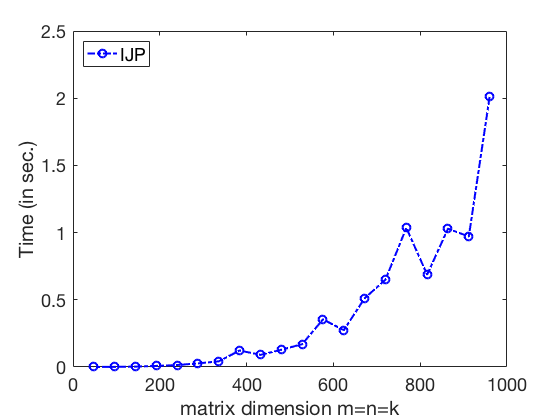

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% Plot time data for reference 
% plot( data(:,1), data(:,2), ...
%      'MarkerSize', 8, 'LineWidth', 2, ...
%      'DisplayName', 'reference', 'Color', [0 0 0] );
             
% Plot time data for IJP                
plot( data(:,1), data(:,4), ...
      'MarkerSize', 8, 'LineWidth', 2, ...
      'DisplayName', 'IJP', 'Marker', 'o', ...
      'LineStyle', '-.', 'Color', [0 0 1] );          

  % Create ylabel
ylabel( 'Time (in sec.)', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northwest','FontSize',18);

% Adjust the x-axis and y-axis range to start at 0
v = axis;                  % extract the current ranges of the graph
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

hold off

## Plotting performance (rate of computation)

We will often examine the rate at which Gemm_IJP.c  compute rather than the time required for completing the computation.

- When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  

- This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  

- Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.  This is reported computed in the third (for the reference implementation) and fifth colum (for IJP) of the data file. 

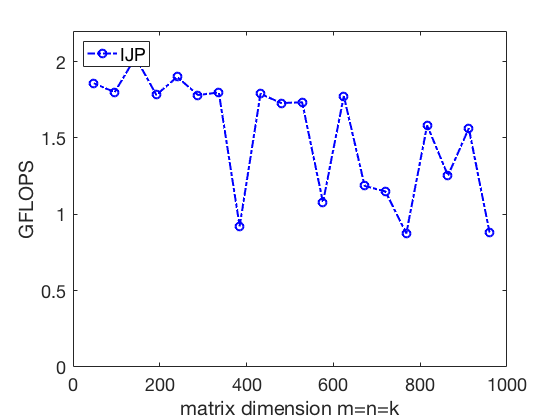

% turbo_clock_rate = 2.6;
% flops_per_cycle = 16;
% peak_gflops = 2.6 * 16;

% Create figure
figure2 = figure('Name','Figure2');

% Create axes
axes2 = axes('Parent',figure2);
hold(axes2,'on');

% Plot time data for reference 
% plot( data(:,1), data(:,3), ...
%       'MarkerSize', 8, 'LineWidth', 2, ...
%       'DisplayName', 'reference', 'Color', [0 0 0] );
             
% Plot time data for IJP                
plot( data(:,1), data(:,5), ...
      'MarkerSize', 8, 'LineWidth', 2, ...
      'DisplayName', 'IJP', 'Marker', 'o', ...
      'LineStyle', '-.', 'Color', [0 0 1] );

% Create ylabel
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes2,'on');
% Set the remaining axes properties
set(axes2,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend2 = legend(axes2,'show');

set(legend2,'Location','northwest','FontSize',18);

% Adjust the x-axis and y-axis range to start at 0
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )

% axis( [ 0 v(2) 0 peak_gflops ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
